# Section 1: Create X

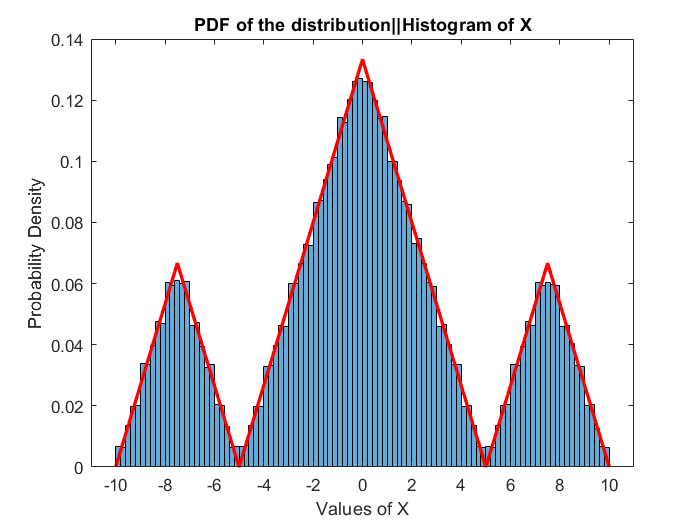

% clearvars;
% clear all;
% close all;
m = 2/75;
x = -10:0.5:10;
x2 = x.^2;
Fx = ((m*(x2/2 + 10*x) + 4/3 ).*rang(x,-10,-7.5)  ) + ((-m*(x2/2 + 5*x)-0.25 + (1/12)).*rang(x,-7.5,-5) ) ...
    + ((m*(x2/2 + 5*x)+(1/3) + (1/6)).*rang(x,-5,0)) + ((-m*(x2/2 - 5*x) + 0.5).*rang(x,0,5)) ...
    + ((m*(x2/2 - 5*x)+(5/6)+(1/3)).*rang(x,5,7.5)) + ((-m*(x2/2 - 10*x)-1.25 + (11/12)).*rang(x,7.5,10)) ;

fx = (m*(x + 10).*rang(x,-10,-7.5)) + (-m*(x + 5).*rang(x,-7.5,-5)) ...
    + (m*(x + 5).*rang(x,-5,0)) + (-m*(x - 5).*rang(x,0,5)) ...
    + (m*(x - 5).*rang(x,5,7.5)) + (-m*(x - 10).*rang(x,7.5,10)) ;

% plot(x,Fx);
N = 1e6 ;
F_dist = makedist('PiecewiseLinear', 'x', x, 'Fx', Fx);
X = random(F_dist, 1, N);
histogram(X, 'Normalization', 'pdf')
hold on
plot(x, fx, 'r', 'LineWidth', 2)
title("PDF of the distribution||Histogram of X");
xlabel("Values of X");
ylabel("Probability Density");

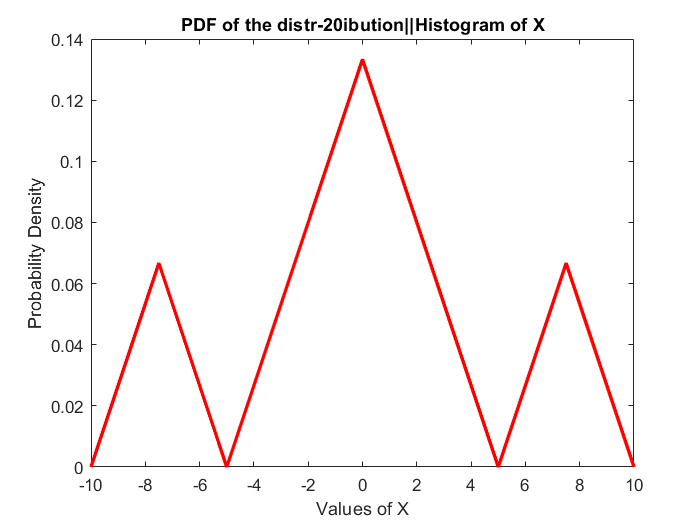

figure;
plot(x, fx, 'r', 'LineWidth', 2)
title("PDF of the distr-20ibution||Histogram of X");
xlabel("Values of X");
ylabel("Probability Density");

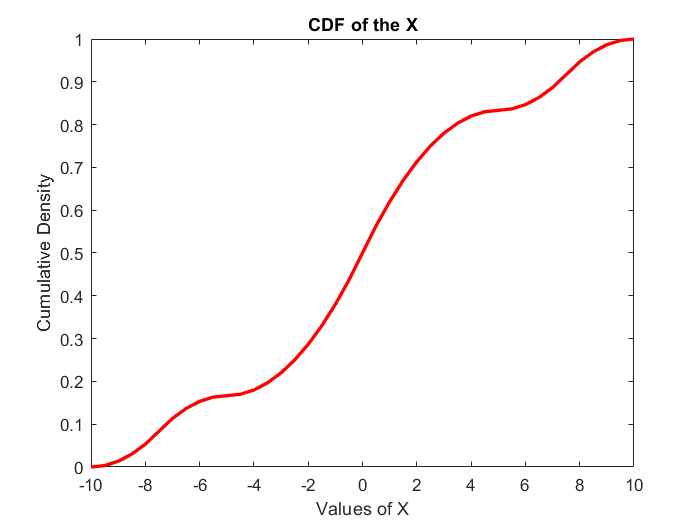


figure;
plot(x, Fx, 'r', 'LineWidth', 2)
title("CDF of the X");
xlabel("Values of X");
ylabel("Cumulative Density");

# Section 2: Create Y

Y = zeros(1,N);
Y(1) = 0;
for i = [2:N]
    Y(i) = X(i) +0.5*X(i-1);
end

# Section 3: Plot Y

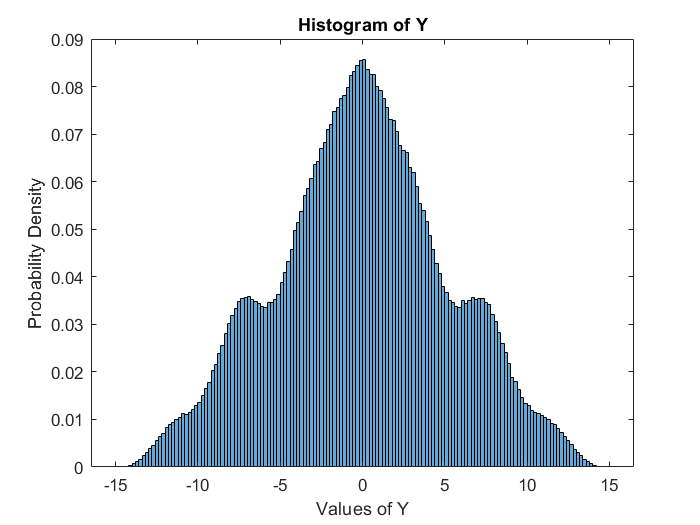

y = -15:0.5:15;
figure;
histogram(Y, 'Normalization', 'pdf')
title("Histogram of Y");
xlabel("Values of Y");
ylabel("Probability Density");

# Section 4: Quantize Y

MSE = 1e-4;
delta = sqrt(12*MSE);
bins = ceil((30)/delta);
[partition,codebook,MSE_calculated] = lloyds(Y,bins); %Max-Lloyd Algorithm

# Section 5: Create list of symbols

[symbols,quantized_sample,distor] = quantiz(Y,partition,codebook);
symbols

symbols =    433   276   219   369   641   440   402   507   304   429   613   698   717   315   306   475   440   454   466   636   507   596   464   627   546   479   206   388   499   669   496   651   550   459   475   358   618   764   441   369   344   402   556   489   368   221   275   162   359   476


# Section 5, calculating TPM for correct entropy

L = length(codebook); %%Number of symbols
TPM = zeros(L,L);
code_count = zeros(1,L);%Store the number of occurences of codes

for i = [1:1:N-1]%%Go over all samples of 
    code_count(symbols(i)+1) = code_count(symbols(i)+1) + 1;
    TPM( symbols(i)+1 , symbols(i+1)+1 ) = TPM( symbols(i)+1 ,symbols(i+1)+1 ) + 1;
end

for i = [1:L]
    for j = [1:L]
        TPM(i,j) = TPM(i,j) /code_count(i);
        if(code_count(i) == 0)
            TPM(i, j) = 0;
        end
        
    end
end

# Section 6: Converting code_count to code probabilities

code_prob = zeros(1,L);
for i = [1:L]
    code_prob(i) = code_count(i)/(N-1);%% Convert to probability
end
sum(code_prob)

ans = 1

# Section 7: Using code_prob as the stationary probabilities

Hx = 0;
for i = [1:L]
    row_sum = 0;
    for j = [1:L]
        if(TPM(i,j)~=0)
            row_sum = row_sum + TPM(i,j) * log2(TPM(i,j));
        end
    end
    Hx = Hx + code_prob(i)*row_sum;
end
Hx = -Hx;
Hx

Hx = 8.6430

# Section 8: Huffman encoding

symbol_list = [0:866];%%These are all the symbols in the vocab
%%We will use this as the probabilities of the symbols
dict = huffmandict(symbol_list,code_prob);

# Section 9: Average bit rate in Huffman encoding

symbol_lengths = zeros(1,length(symbol_list));
for sy = [symbol_list]
    symbol_lengths(sy+1) = length(dict{sy+1,2});
end
avg_length_huff = 0;

for sy = [symbol_list]
    avg_length_huff = avg_length_huff + code_prob(sy+1)*symbol_lengths(sy+1);
end
avg_length_huff

avg_length_huff = 9.3091

function [arr] = rang(x,n1,n2)
%n1 < n2
arr = heaviside(x-n1) - heaviside(x-n2);
end